# Word Puzzle Cheater

I have been obsessed with a little word puzzle on my phone.

Sometimes I got stuck and decided to write a small script to generate all valid words, to help me get unstuck. 

Here a drawing of my iPhone app.

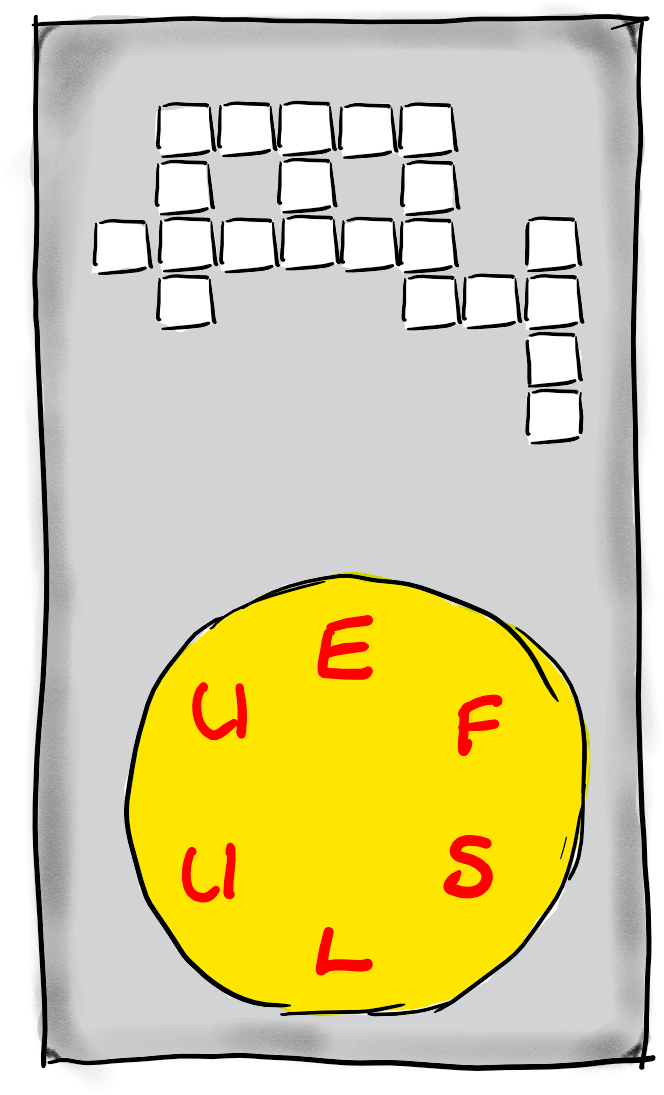

Below the code you can run to generate the valid words for the puzzle.

### Load the dictionary 

You can load your list of valid words from a text file. The results are going to be validated using the words from this list. This means, results are going to be as good as your dictionary is. I have found a 12 english dictionaries provided by ***Keith Vertanen*** on this location: [https://www.keithv.com/software/wlist](https://www.keithv.com/software/wlist). You can load of of these by using the command: `words = textread('wlist_match10.txt', '%s');` 

You can also load the words from an online repository.  Below, I am loding the words from a dictionary file which is part of the **GitHub** repository [https://github.com/dwyl/english-words](https://github.com/dwyl/english-words)

str = webread('https://raw.githubusercontent.com/dwyl/english-words/master/words.txt');
words = strsplit(str, newline);
words = string(words);
fprintf('Dictionary total words: %d', length(words));

Dictionary total words: 466552

### Find possible words using provided characters

Type here the letters of your puzzle

letters = 'unpgel';

Create all valid permutations

P = perms(letters);

count = 0;
valid = {};
for i=1:size(P,1)
    permutationI = P(i, :);
    for j=3:length(permutationI)
        current = permutationI(1:j);
        found = find(words == current);
        if ~isempty(found)
            count = count + 1;
            valid = [valid current]; %#ok<AGROW> 
        end
    end
end

Select and display all unique valid words

valid = unique(valid)';
fprintf('Words found: %d', length(valid));

Words found: 37

disp(valid);

    'engl'
    'enl'
    'gen'
    'genu'
    'glue'
    'gneu'
    'gue'
    'gul'
    'gule'
    'gulp'
    'gunl'
    'gup'
    'leg'
    'leng'
    'lep'
    'leu'
    'leung'
    'lue'
    'luge'
    'lung'
    'lunge'
    'pelu'
    'peng'
    'plu'
    'plug'
    'plunge'
    'pug'
    'pule'
    'pun'
    'pung'
    'pungle'
    'ule'
    'ung'
    'unl'
    'unp'
    'unpeg'
    'upleg'
